2.) Here we are going to explore the harvesting function h(y) as y gets large

%Observation on the amount of harvesting

p = 10; %p & q values represent the effectivness of the locals catching fish
q = 115;

y = 1:1:120; %Array from 1-120
h = (p * y.^(2)) ./ (q + y.^(2)) %The amount of harvesting

h =     0.0862    0.3361    0.7258    1.2214    1.7857    2.3841    2.9878    3.5754    4.1327    4.6512    5.1271    5.5598    5.9507    6.3023    6.6176    6.9003    7.1535    7.3804    7.5840    7.7670    7.9317    8.0801    8.2143    8.3357    8.4459    8.5461    8.6374    8.7208    8.7971    8.8670    8.9312    8.9903    9.0449    9.0952    9.1418    9.1850    9.2251    9.2623    9.2971    9.3294    9.3597    9.3880    9.4145    9.4393    9.4626    9.4845    9.5052    9.5246    9.5429    9.5602


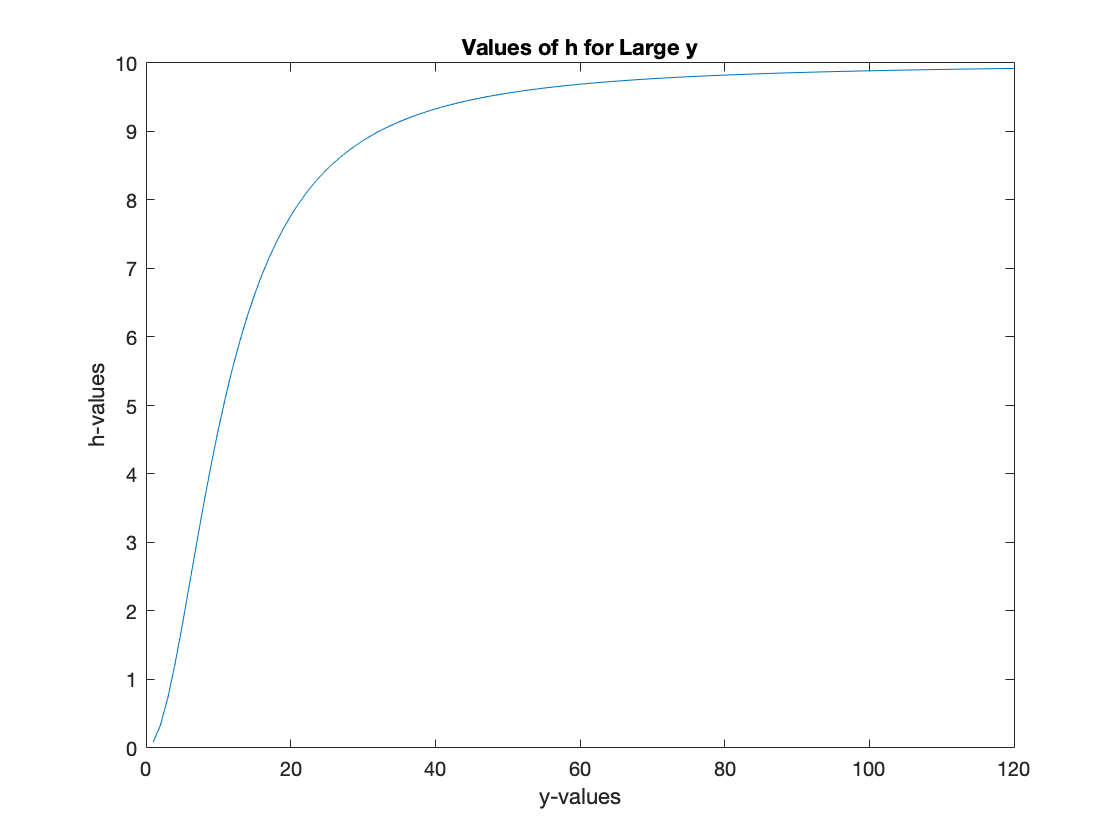


%Plot of harvesting for large values of y
plot(y,h)
title('Values of h for Large y')
xlabel('y-values')
ylabel('h-values')

It seems that as $y\longrightarrow \infty$the amount of harvesting approaches the p values

Here we are going to observe what happens as y$\longrightarrow 0$

%Observation on the amount of harvesting

p1 = 12; %p & q values represent the effectivness of the locals catching fish
q1 = 115;

y1 = 1:-0.001:0.001; %Array from 1-120
h1 = (p1 * y1.^(2)) ./ (q1 + y1.^(2)) %The amount of harvesting

h1 =     0.1034    0.1032    0.1030    0.1028    0.1026    0.1024    0.1022    0.1020    0.1018    0.1016    0.1014    0.1012    0.1010    0.1008    0.1006    0.1004    0.1002    0.1000    0.0998    0.0996    0.0994    0.0992    0.0990    0.0988    0.0986    0.0984    0.0982    0.0980    0.0978    0.0976    0.0974    0.0972    0.0970    0.0968    0.0966    0.0964    0.0962    0.0960    0.0958    0.0956    0.0954    0.0952    0.0950    0.0948    0.0946    0.0944    0.0942    0.0940    0.0938    0.0936


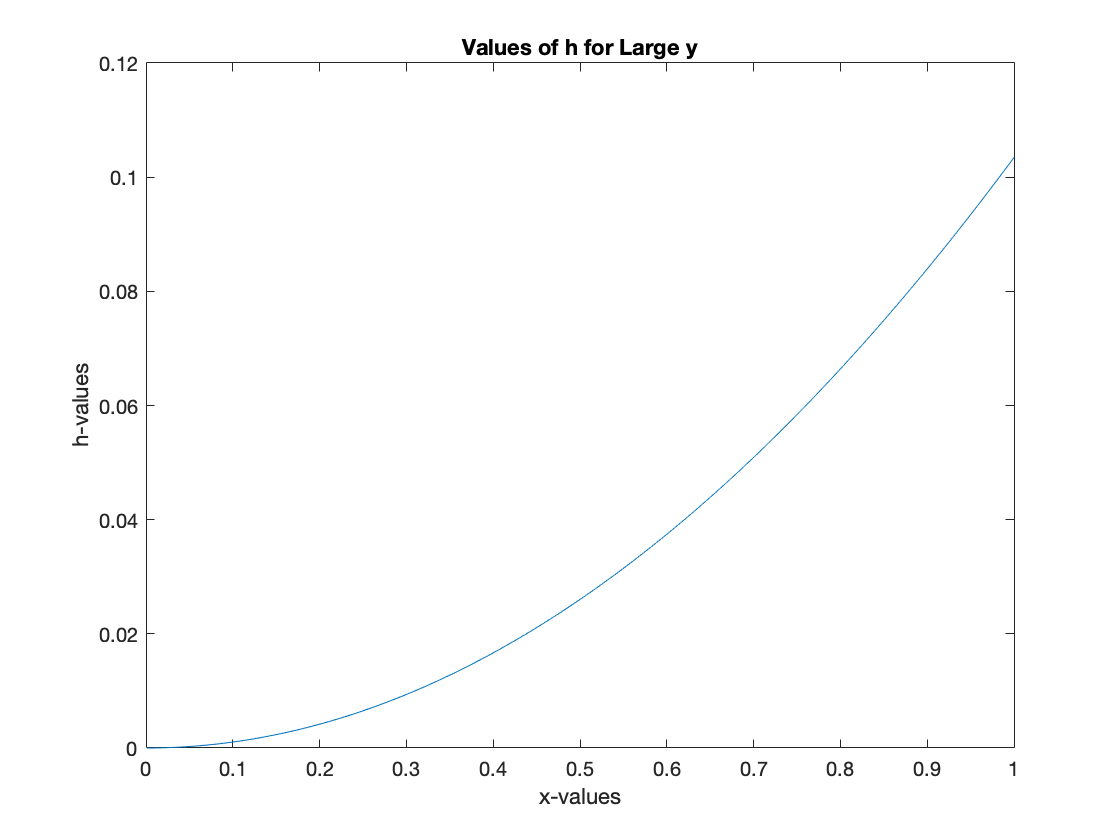


%Plot of harvesting for large values of y
plot(y1,h1)
title('Values of h for Large y')
xlabel('x-values')
ylabel('h-values')

5.) p = 1.2 and q = 1 and suppose there are different trout in the lake. r (growth rate) = 0.65, but L(carrying capacity is different). 

Rainbow trout: L = 5.4

Brown trout: L = 8.1

Brook trout: L = 16.3

Plots for all the different values of L

%Plots of f(y) for different values of L

p2 = 1.2; %Proportion of the number of people fishing
q2 = 1;   %Effect of water temperature on fish
r = 0.65; %Growth Rate

%Plotting
y2 = 0:0.1:20;

for L = [5.4 8.1 16.3]
    disp(L)
    fy = (r .* (1 - (y2 ./ L)) .* y2) - ((p2 .* y2.^(2)) ./ (q2 + y2.^(2)))
    
    %Plotting the function
    %figure(1)
    plot(y2,fy)
    hold on
    title('Trout Plot of f(y)')
    xlabel('y')
    ylabel('f(y)')
    grid on
    
    %Find the roots of the function
    zero = fzero(@(y2) (r .* (1 - (y2 ./ L)) .* y2) - ((p2 .* y2.^(2)) ./ (q2 + y2.^(2))),[0 10])
end

    5.4000



fy =          0    0.0519    0.0790    0.0851    0.0752    0.0549    0.0290    0.0014   -0.0253   -0.0495   -0.0704   -0.0877   -0.1015   -0.1123   -0.1205   -0.1266   -0.1311   -0.1344   -0.1370   -0.1392   -0.1415   -0.1440   -0.1471   -0.1510   -0.1558   -0.1618   -0.1691   -0.1777   -0.1880   -0.1998   -0.2133   -0.2287   -0.2458   -0.2649   -0.2859   -0.3090   -0.3340   -0.3612   -0.3904   -0.4218   -0.4553   -0.4910   -0.5290   -0.5691   -0.6114   -0.6560   -0.7029   -0.7520   -0.8034   -0.8571


zero = 0

    8.1000



fy =          0    0.0523    0.0806    0.0887    0.0816    0.0649    0.0435    0.0210    0.0003   -0.0170   -0.0302   -0.0391   -0.0438   -0.0445   -0.0419   -0.0363   -0.0284   -0.0184   -0.0070    0.0056    0.0190    0.0329    0.0471    0.0613    0.0753    0.0890    0.1022    0.1148    0.1266    0.1376    0.1478    0.1569    0.1650    0.1720    0.1779    0.1825    0.1860    0.1881    0.1890    0.1885    0.1866    0.1834    0.1788    0.1728    0.1654    0.1565    0.1461    0.1343    0.1210    0.1063


zero = 0

   16.3000



fy =          0    0.0527    0.0823    0.0923    0.0881    0.0750    0.0580    0.0408    0.0262    0.0157    0.0101    0.0097    0.0144    0.0237    0.0372    0.0545    0.0750    0.0982    0.1238    0.1513    0.1805    0.2110    0.2425    0.2748    0.3078    0.3413    0.3751    0.4090    0.4431    0.4772    0.5111    0.5449    0.5784    0.6117    0.6446    0.6771    0.7092    0.7408    0.7719    0.8025    0.8326    0.8620    0.8909    0.9192    0.9469    0.9740    1.0003    1.0261    1.0511    1.0755


zero = 0

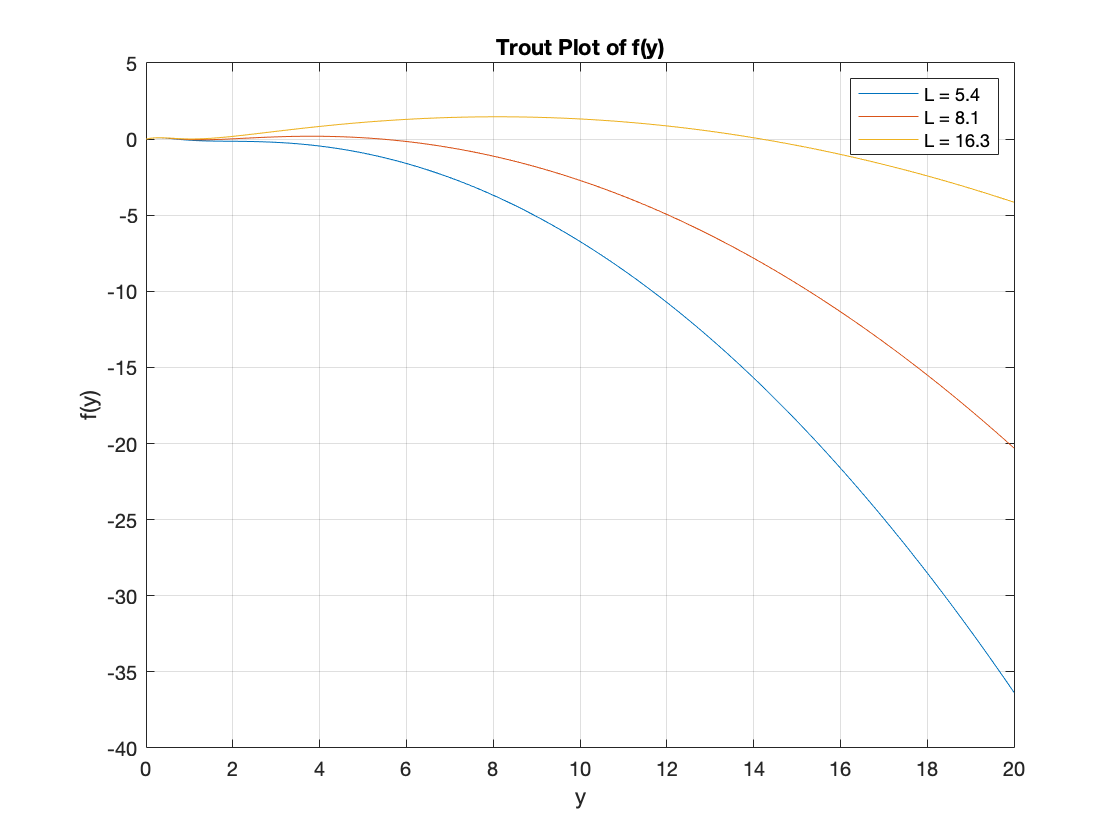

legend('L = 5.4','L = 8.1','L = 16.3')

Here we are going to find the roots for each of the carrying capacities

When L = 5.4

%When the carrying cappacity L = 5.4
L1 = 5.4;
y3 = 0:0.1:5;
fy1 = (r .* (1 - (y3 ./ L1)) .* y3) - ((p2 .* y3.^(2)) ./ (q2 + y3.^(2)))

fy1 =          0    0.0519    0.0790    0.0851    0.0752    0.0549    0.0290    0.0014   -0.0253   -0.0495   -0.0704   -0.0877   -0.1015   -0.1123   -0.1205   -0.1266   -0.1311   -0.1344   -0.1370   -0.1392   -0.1415   -0.1440   -0.1471   -0.1510   -0.1558   -0.1618   -0.1691   -0.1777   -0.1880   -0.1998   -0.2133   -0.2287   -0.2458   -0.2649   -0.2859   -0.3090   -0.3340   -0.3612   -0.3904   -0.4218   -0.4553   -0.4910   -0.5290   -0.5691   -0.6114   -0.6560   -0.7029   -0.7520   -0.8034   -0.8571


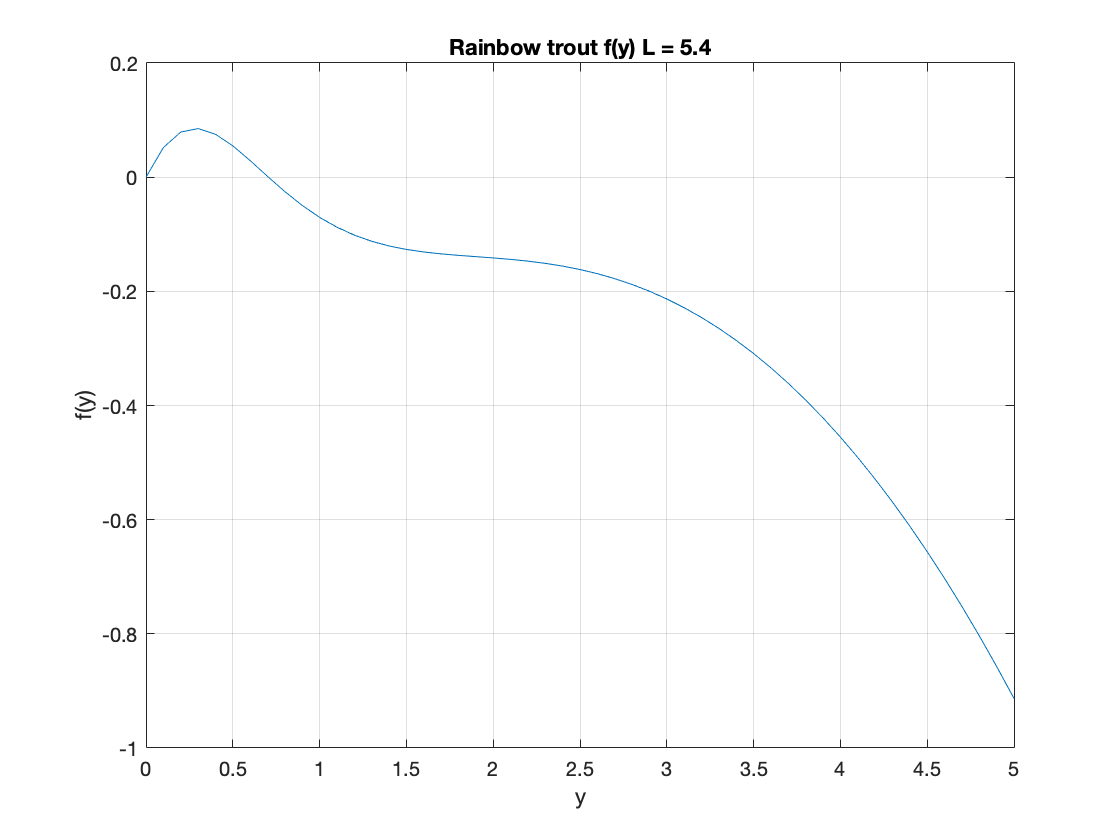


% Observing where fy1 intersects the x-axis (roots)
figure(2)
plot(y3,fy1)
title('Rainbow trout f(y) L = 5.4')
xlabel('y')
ylabel('f(y)')
grid on 


%The estimated number of roots is 2 (0,0.7)
%Finding the roots when L = 5.4
zero1 = fzero(@(y3) (r .* (1 - (y3 ./ L1)) .* y3) - ((p2 .* y3.^(2)) ./ (q2 + y3.^(2))), 0.7)

zero1 = 0.7050

disp(zero1)

    0.7050




%There is a zero at 0.7050

When L = 8.1

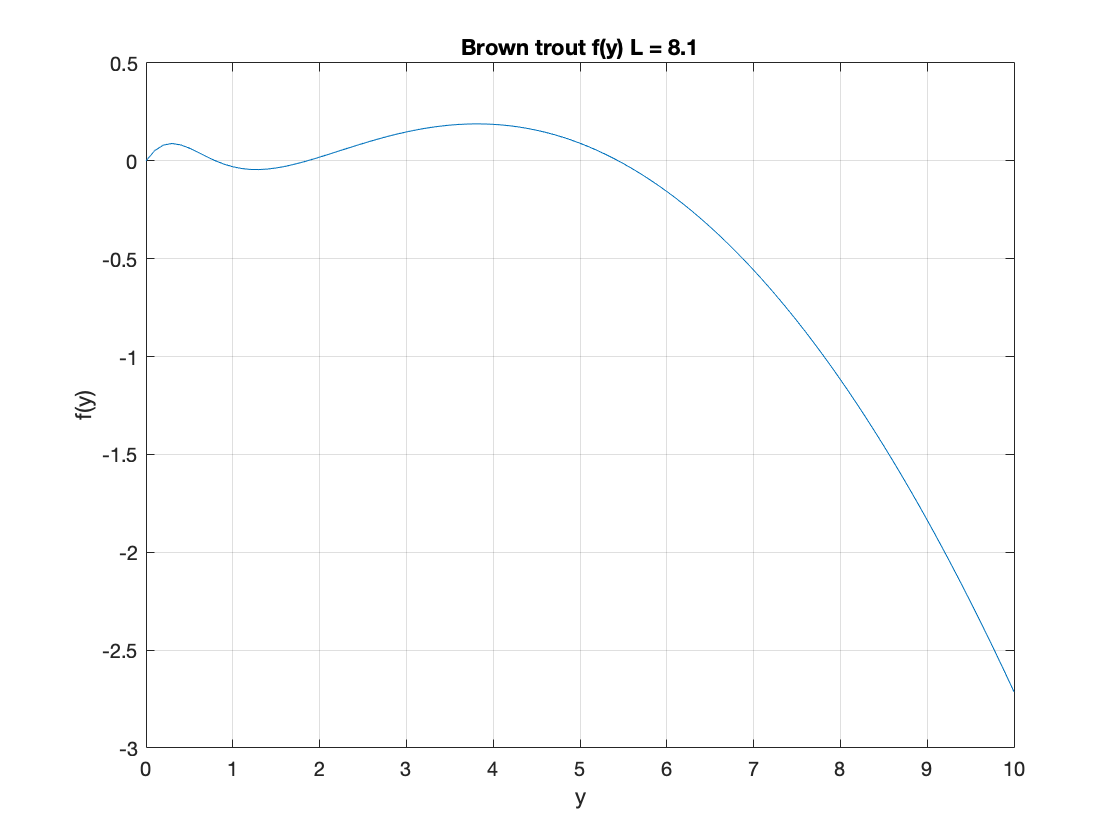

%When carrying capacity L = 8.1
L2 = 8.1;
y4 = 0:0.1:10;
fy2 = (r .* (1 - (y4 ./ L2)) .* y4) - ((p2 .* y4.^(2)) ./ (q2 + y4.^(2)));

%Plotting f(y) when L = 8.1
figure(3)
plot(y4,fy2)
title('Brown trout f(y) L = 8.1')
xlabel('y')
ylabel('f(y)')
grid on


%The estimated number of roots is (0,0.8,1.8,5.44)
for r1 = [0 0.8 1.8 5.44]
    zero2 = fzero(@(y4) (r .* (1 - (y4 ./ L2)) .* y4) - ((p2 .* y4.^(2)) ./ (q2 + y4.^(2))),r1)
end

zero2 = 0

zero2 = 0.8018

zero2 = 1.8564

zero2 = 5.4418


%There are zeros at y2 = 0.8018 1.8564 5.4418

When L = 16.3

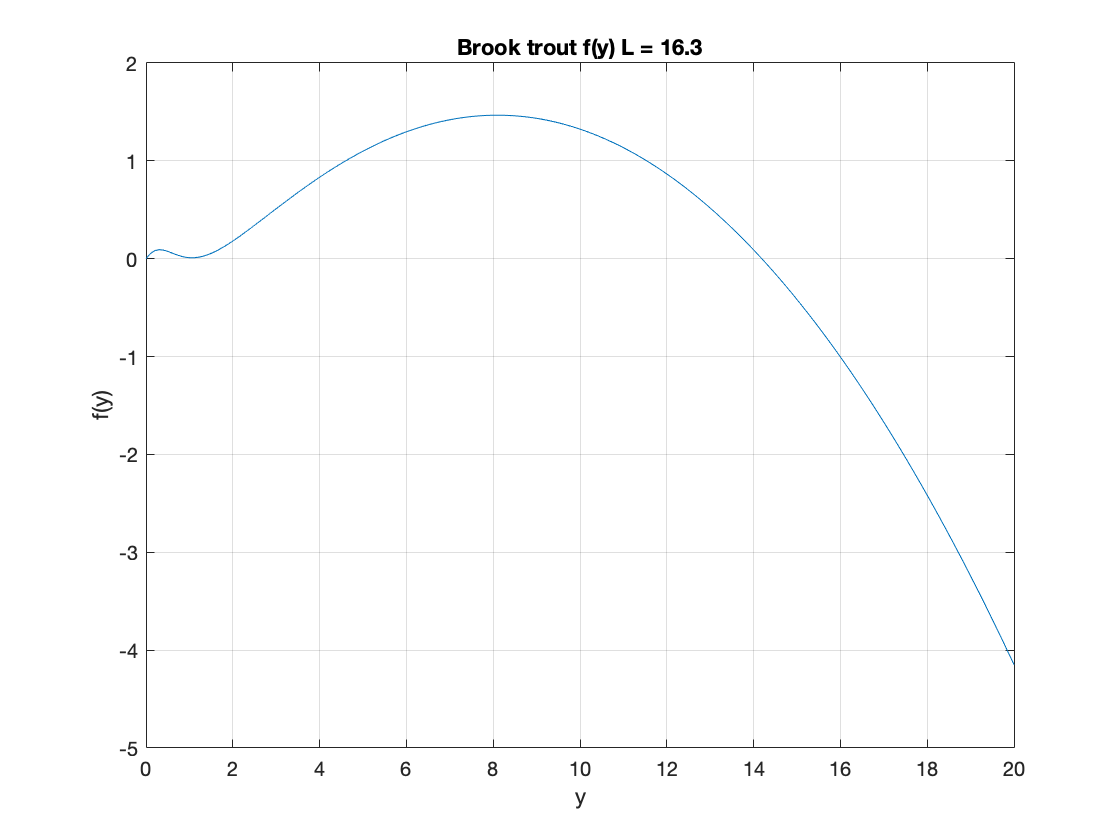

%When carrying capacity is L = 16.3
L3 = 16.3;
y5 = 0:0.1:20;
fy3 = (r .* (1 - (y5 ./ L3)) .* y5) - ((p2 .* y5.^(2)) ./ (q2 + y5.^(2)));

%Plotting f(y) when L = 16.3
figure(3)
plot(y5,fy3)
title('Brook trout f(y) L = 16.3')
xlabel('y')
ylabel('f(y)')
grid on


%The estimated number of roots (0,14.9)
for r2 = [0 14.9]
    zero3 = fzero(@(y5)(r .* (1 - (y5 ./ L3)) .* y5) - ((p2 .* y5.^(2)) ./ (q2 + y5.^(2))),r2)
end

zero3 = 0

zero3 = 14.1898


%There are zeros at y2 = 14.1898

b) By trial and error find values of L ranging from 5.4 to 16.3 where we see a change in equilibria (the number of times the function crosses the x-axis)

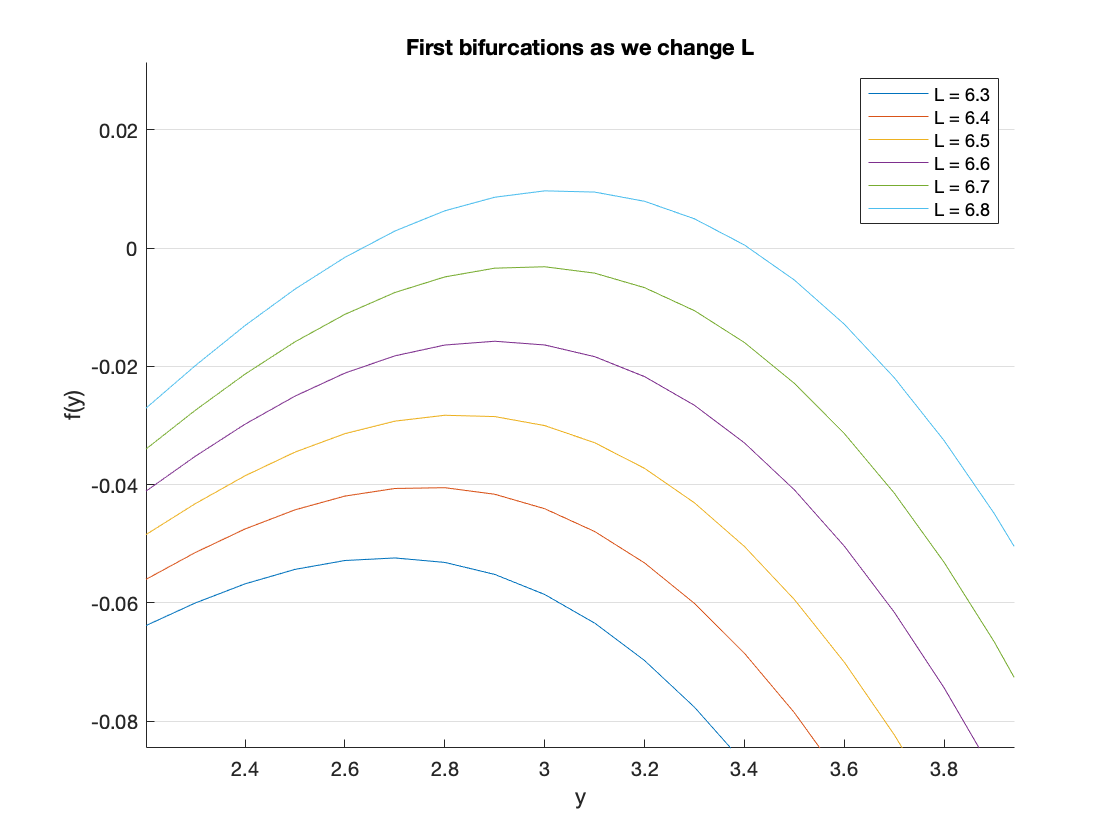

%Here we are fiding the first bifurcation value

%Define the range of the graph
y6 = 0:0.1:20;

%Itterating over values of L between 6.3 and 6.8 and plotting
for L4 = 6.3:0.1:6.8
    fy4 =  (r .* (1 - (y6 ./ L4)) .* y6) - ((p2 .* y6.^(2)) ./ (q2 + y6.^(2)));
    
    %Plotting L values
    figure(4)
    hold on
    plot(y6,fy4)
    title('First bifurcations as we change L')
    xlabel('y')
    ylabel('f(y)')
    
    %Edit the output of the graph
    set(gca,'XGrid','off','YGrid','on')
    xlim([0 6])
    ylim([-0.2 0.2])
end
hold off
legend('L = 6.3','L = 6.4','L = 6.5','L = 6.6','L = 6.7','L = 6.8')

%Here we see bifurcation when L is equal to 6.8

We are going to find the second bifurcation value by altering the interval of our for loop

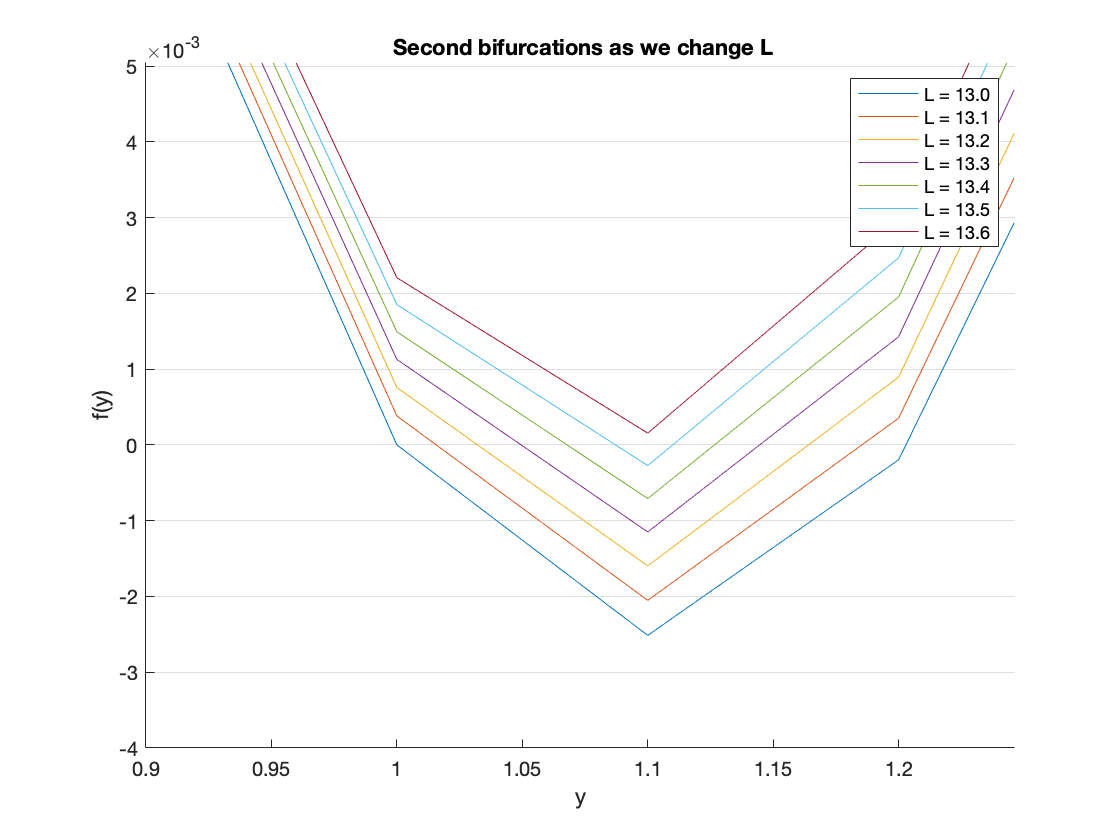

%Here we are fiding the second bifurcation value

%Itterating over values of L between 6.3 and 6.8 and plotting
for L5 = 13.0:0.1:13.6
    fy4 =  (r .* (1 - (y6 ./ L5)) .* y6) - ((p2 .* y6.^(2)) ./ (q2 + y6.^(2)));
    
    %Plotting L values
    figure(5)
    hold on
    plot(y6,fy4)
    title(' Second bifurcations as we change L')
    xlabel('y')
    ylabel('f(y)')
    
    %Edit the output of the graph
    set(gca,'XGrid','off','YGrid','on')
    xlim([0.9 1.246])
    ylim([-0.004 0.00504])
end
hold off
legend('L = 13.0','L = 13.1','L = 13.2','L = 13.3','L = 13.4','L = 13.5','L = 13.6')

%Here we see bifurcation when L is equal to 13.6

c.) Plotting the Direction Field

L = 5.4

%When L = 5.4
f = @(t,y) (0.65 .* (1 - (y ./ 5.40)) .* y) - ((1.20 .* y.^(2)) ./ (1.0 + y.^(2)))

f = function_handle with value:
    @(t,y)(0.65.*(1-(y./5.40)).*y)-((1.20.*y.^(2))./(1.0+y.^(2)))


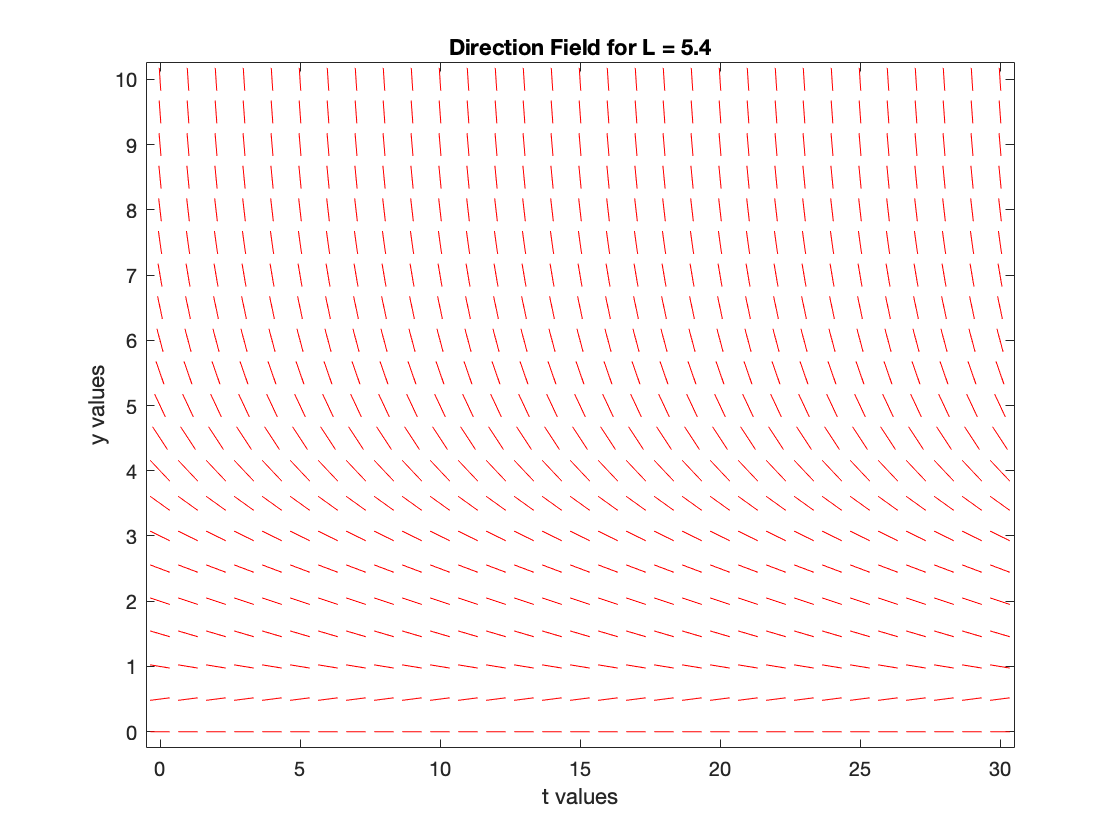

dirfield(f,0:1:30,0:0.5:10,'Direction Field for L = 5.4')

L = 8.1

%When L = 8.1
f = @(t,y) (0.65 .* (1 - (y ./ 8.10)) .* y) - ((1.20 .* y.^(2)) ./ (1.0 + y.^(2)))

f = function_handle with value:
    @(t,y)(0.65.*(1-(y./8.10)).*y)-((1.20.*y.^(2))./(1.0+y.^(2)))


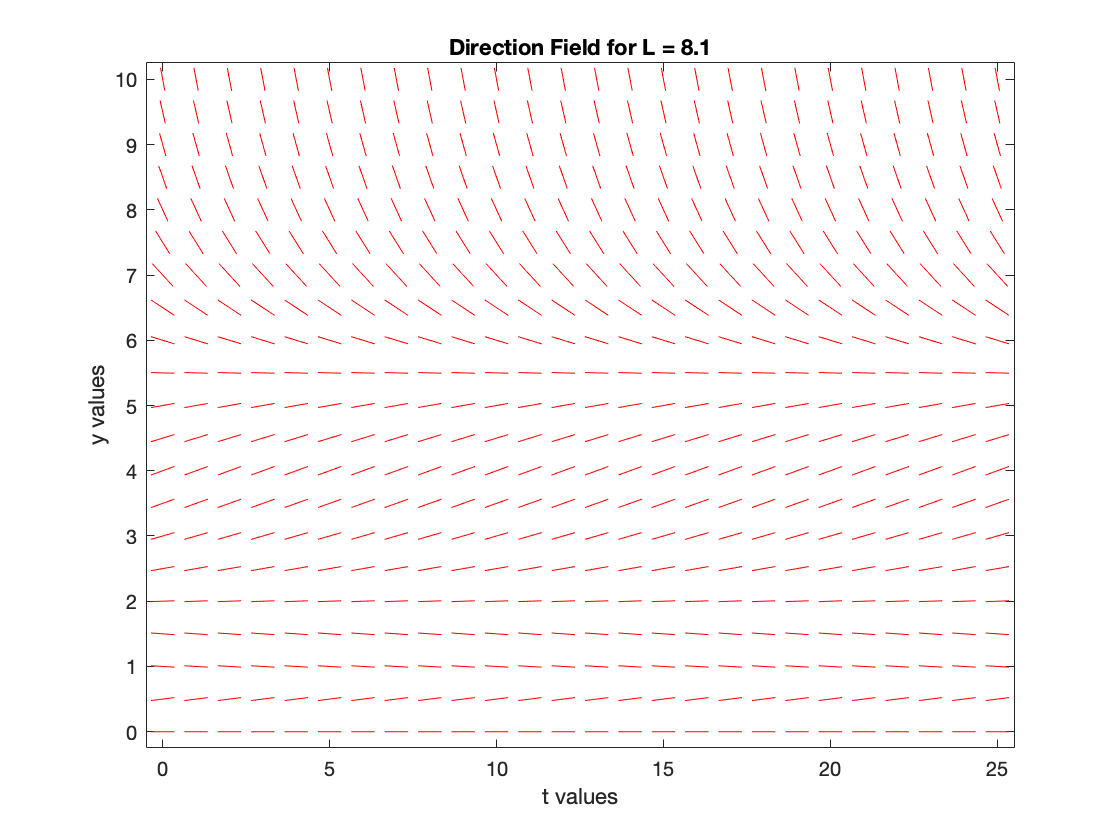

dirfield(f,0:1:25,0:0.5:10,'Direction Field for L = 8.1')

L = 16.3

%When L = 16.3
f = @(t,y) (0.65 .* (1 - (y ./ 16.3)) .* y) - ((1.20 .* y.^(2)) ./ (1.0 + y.^(2)))

f = function_handle with value:
    @(t,y)(0.65.*(1-(y./16.3)).*y)-((1.20.*y.^(2))./(1.0+y.^(2)))


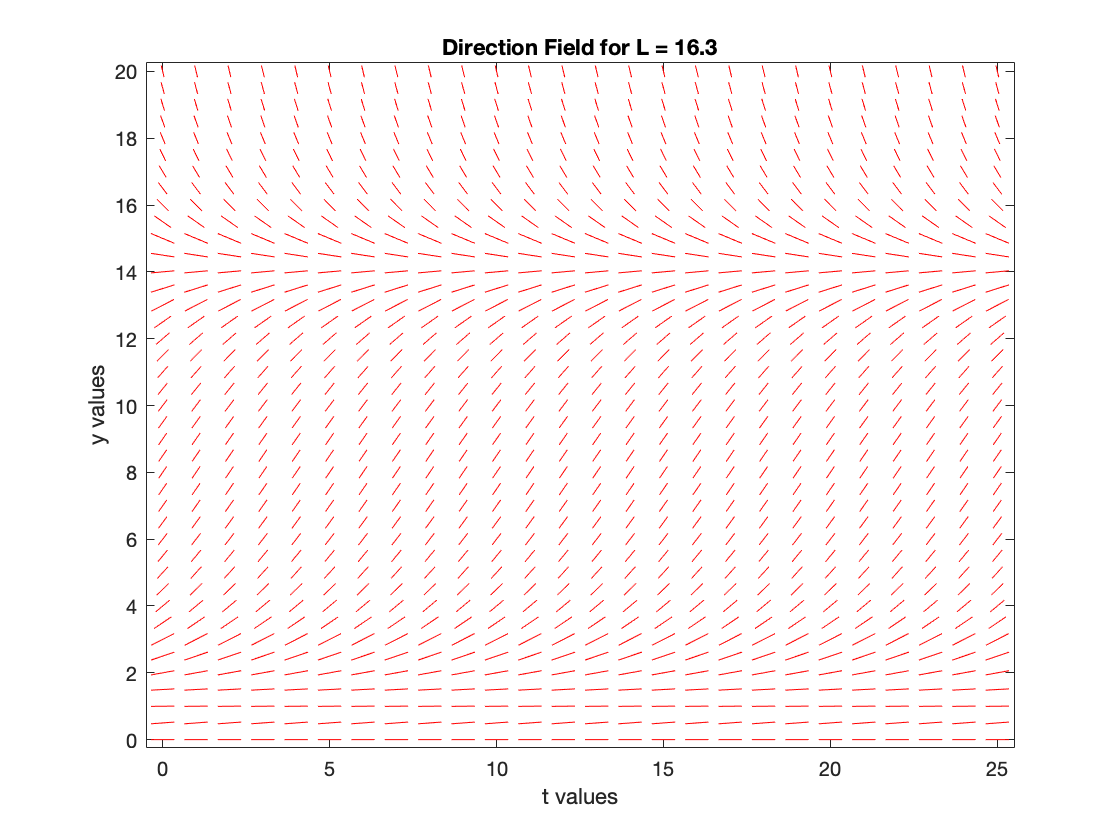

dirfield(f,0:1:25,0:0.5:20,'Direction Field for L = 16.3')

7.) Use Eulers Method with step size h = 0.01 estimate the whole number of fish present in the lake after 60 days.

a.) Euler's Method for the 

%Here is the following code for Euler's Method in relation to Rainbow Trout
%L = 5.4